## **Reto: Detección de Malaria**

**Integrantes:**

- Damaris Mariel Ramos Mariscal - A01648054

- Ian Santiago Hernández Vaca - A01647114

- Ana Valentina Rentería Meza - A01649359

- Daniel Alejandro Martínez Navarro - A01648171

- Yael Alejandro López Márquez - A01649284

**Introducción:**

La simulación del campo eléctrico es fundamental para comprender el comportamiento de sistemas con cargas distribuidas. En este trabajo se modela el campo eléctrico generado por dos placas paralelas utilizando una aproximación discreta basada en cargas puntuales.

El cálculo se realiza mediante el principio de superposición, el cual establece que el campo eléctrico total es la suma de los campos individuales generados por cada carga:

#### 1. Parámetros

- Se limpia el entorno de trabajo para evitar interferencias con variables anteriores

- Se define la constante **k=1** para simplificar el modelo físico. 

- Cada placa se modela como un **conjunto discreto de cargas puntuales**. 

- `num_cargas` indica cuántas cargas tendrá cada placa. 

- `alto` distribuye las cargas uniformemente en el eje **y**. 

- `x_izq` y `x_der` representan la posición de cada placa en el eje **x**.

clear; clc; close all;

k = 1;
num_cargas = 3;                
alto = linspace(-1.8, 1.8, num_cargas);
x_izq = -0.5;   % placa positiva
x_der =  0.5;   % placa negativa


#### 2. Malla 2D

- Se genera una malla bidimensional donde se calculará el campo eléctrico. 

- Cada punto **(x,y)** representa una posición en el plano. 

- `Ex` y `Ey` almacenan las componentes del campo eléctrico en cada punto. 

- Inicialmente se asignan en cero porque se sumarán contribuciones.

[x, y] = meshgrid(-2.5:0.15:2.5, -2.5:0.15:2.5);
Ex = zeros(size(x));
Ey = zeros(size(y));

#### 3. Superposición 

- Se aplica el **principio de superposición**: el campo total es la suma de los campos individuales. 

- Para cada carga: 

- Se calcula el vector posición **(rx,ry)(r_x, r_y)(rx�,ry�)**

- Se obtiene la distancia **r**

- Se calcula el campo eléctrico proporcional a **1/r^3�**

- Se consideran: 

- Cargas positivas en la placa izquierda 

- Cargas negativas en la placa derecha 

- Se evita división entre cero reemplazando valores problemáticos (`NaN` o `eps`).

for i = 1:num_cargas
    % Placa positiva
    rx = x - x_izq;
    ry = y - alto(i);

    r = sqrt(rx.^2 + ry.^2);
    r(r==0) = NaN;

    Ex = Ex + k*1*rx./(r.^3);
    Ey = Ey + k*1*ry./(r.^3);
    
    % Placa negativa
    rx = x - x_der;
    ry = y - alto(i);
    r = sqrt(rx.^2 + ry.^2);
    r(r==0) = eps;
    Ex = Ex + k*(-1)*rx./(r.^3);
    Ey = Ey + k*(-1)*ry./(r.^3);
end


#### 4. Normalizar del campo

- Se calcula la magnitud del campo eléctrico en cada punto.

- Se normalizan los vectores para:

- mantener solo la **dirección**

- evitar flechas demasiado largas o cortas

- Se multiplica por un factor (0.25) para controlar el tamaño visual.

E_mag = sqrt(Ex.^2 + Ey.^2);
E_mag(E_mag==0) = eps;
Ex_norm = Ex./E_mag * 0.25;
Ey_norm = Ey./E_mag * 0.25;


####  5. Graficar campo

- Se usa `quiver` para representar el campo eléctrico como flechas.

- Cada flecha indica:

- dirección del campo

- sentido del movimiento de una carga positiva de prueba

- Se ajusta el grosor con `LineWidth`.

figure;
quiver(x, y, Ex_norm, Ey_norm, 'g', 'LineWidth', 1.2);
hold on;


#### **6. Definición de parámetros geométricos**

- Se definen dimensiones y posición de las placas en 3D.

- `ancho` y `largo` determinan el tamaño del prisma.

- `v` controla la escala del volumen en el eje z.

v = 0.5;
dx = -1; dy = 0; dz = 0;
ancho = 0.2;
largo = 3.6;


#### 7. Función crear prisma

- Esta función genera los **vértices de un prisma rectangular**.

- Se construyen 8 vértices en 3D.

- Se usa para representar visualmente las placas como sólidos.

function vertices = crear_prisma(xc, yc, zc, ancho, largo, v)
    vertices = [
        -v*ancho+xc, -v*largo+yc, -v+zc;
        -v*ancho+xc,  v*largo+yc, -v+zc;
         v*ancho+xc,  v*largo+yc, -v+zc;
         v*ancho+xc, -v*largo+yc, -v+zc;
        -v*ancho+xc, -v*largo+yc,  v+zc;
        -v*ancho+xc,  v*largo+yc,  v+zc;
         v*ancho+xc,  v*largo+yc,  v+zc;
         v*ancho+xc, -v*largo+yc,  v+zc ];
end

#### **8. Definición de caras**

- Cada fila define una cara del prisma mediante índices de vértices.

- Permite a MATLAB construir la superficie con `patch`.

caras = [1 2 3 4; 2 6 7 3; 4 3 7 8; 1 5 8 4; 1 2 6 5; 5 6 7 8];


#### 10. Creación de las placas

- Se generan dos prismas que representan las placas:

- Roja → carga positiva

- Azul → carga negativa

- `FaceAlpha` controla la transparencia.

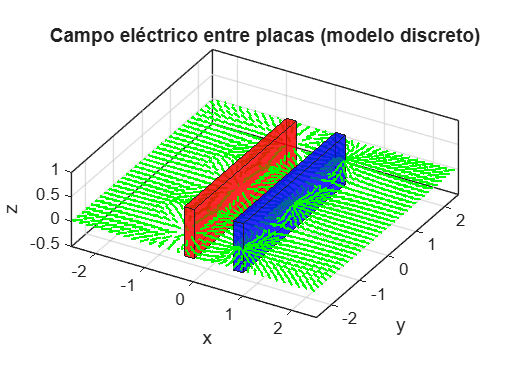

% Placa roja

vertices_roja = crear_prisma(x_izq, dy, dz, ancho, largo, v);
patch('Faces', caras, 'Vertices', vertices_roja, 'FaceColor', 'r', 'FaceAlpha', 0.6);

% Placa azul
vertices_azul = crear_prisma(x_der, dy, dz, ancho, largo, v);
patch('Faces', caras, 'Vertices', vertices_azul, 'FaceColor', 'b', 'FaceAlpha', 0.6);


#### **10. Configuración final de la gráfica**

- `axis` `equal`: mantiene proporciones correctas

- `view(30,30)`: define el ángulo de visualización 3D

- Se agregan etiquetas y título

- Se ajustan límites del sistema para mejor visualización

% Gráficas
axis equal; grid on; view(30,30);
xlabel('x'); ylabel('y'); zlabel('z');
title('Campo eléctrico entre placas (modelo discreto)');
axis([-2.5 2.5 -2.5 2.5 -0.5 1]);

El modelo implementa una aproximación discreta del campo eléctrico generado por placas paralelas mediante la suma de contribuciones de cargas puntuales. La visualización permite observar que el campo tiende a ser uniforme en la región central, lo cual coincide con el comportamiento esperado teóricamente.